Project 3:

sanity check of guassian pdf :

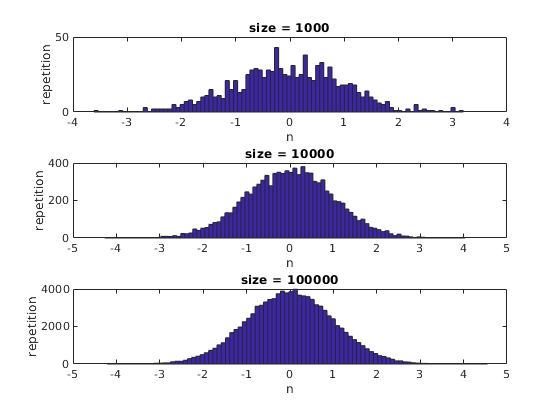

rng shuffle;
mu = 0; sigma = 1;
nbins = 90;

figure;
subplot(3,1,1);
noise = normrnd(mu , sigma ,1000 ,1);
hist(noise , nbins);
title('size = 1000');xlabel('n');ylabel('repetition');

subplot(3,1,2);
noise = normrnd(mu , sigma ,10000 ,1);
hist(noise , nbins);
title('size = 10000');xlabel('n');ylabel('repetition');

subplot(3,1,3);
noise = normrnd(mu , sigma ,100000 ,1);
hist(noise , nbins);
title('size = 100000');xlabel('n');ylabel('repetition');

check how hyper parameter mu and sigma affect pdf estimation:

1.mu:

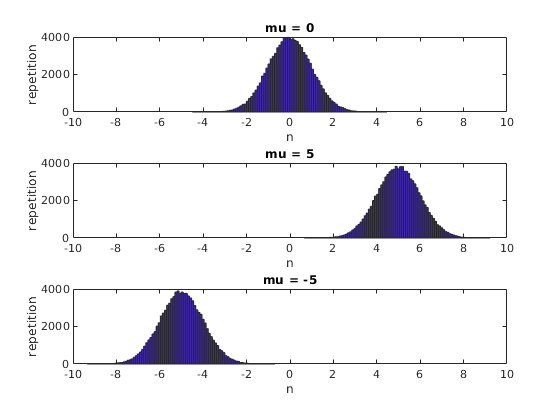

sigma=1;
nbins = 90;

figure;
subplot(3,1,1);
noise = normrnd(0 , sigma ,100000 ,1);
hist(noise , nbins);
title('mu = 0');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(3,1,2);
noise = normrnd(5 , sigma ,100000 ,1);
hist(noise , nbins);
title('mu = 5');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(3,1,3);
noise = normrnd(-5 , sigma ,100000 ,1);
hist(noise , nbins);
title('mu = -5');xlabel('n');ylabel('repetition');xlim([-10,+10]);

2.sigma:

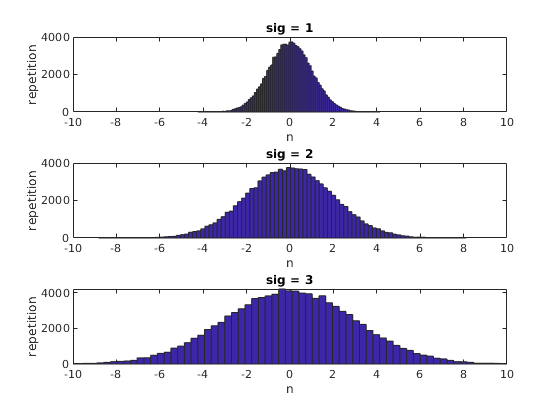

mu=0;
nbins = 90;

figure;
subplot(3,1,1);
noise = normrnd(mu , 1 ,100000 ,1);
hist(noise , nbins);
title('sig = 1');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(3,1,2);
noise = normrnd(mu , 2 ,100000 ,1);
hist(noise , nbins);
title('sig = 2');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(3,1,3);
noise = normrnd(mu , 3 ,100000 ,1);
hist(noise , nbins);
title('sig = 3');xlabel('n');ylabel('repetition');xlim([-10,+10]);

what happend if we add a number to the noise:

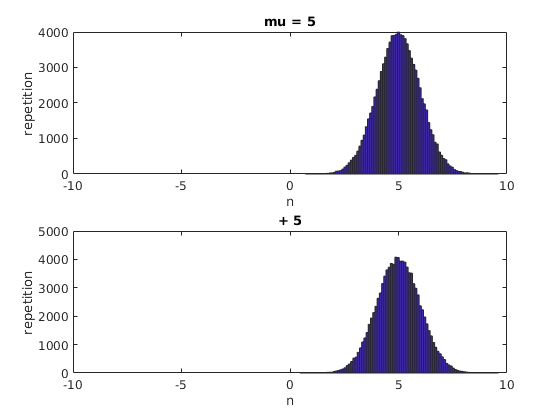

mu = 0; sigma = 1;
nbins = 90;
figure;
subplot(2,1,1);
noise = normrnd(5 , sigma ,100000 ,1);
hist(noise , nbins);
title('mu = 5');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(2,1,2);
noise = normrnd(mu , sigma ,100000 ,1);
hist(noise+5 , nbins);
title('+ 5');xlabel('n');ylabel('repetition');xlim([-10,+10]);

AWGN Channel:

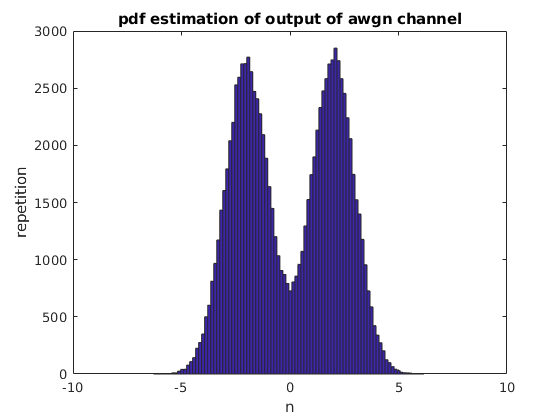

A = 2; sigma = 1; size = 100000; p=0.5;
rec = awgn_ch(A , sigma , size , p);
figure;
hist(rec , nbins);
title('pdf estimation of output of awgn channel');xlabel('n');ylabel('repetition');xlim([-10,+10]);

effect of prior knowledge:

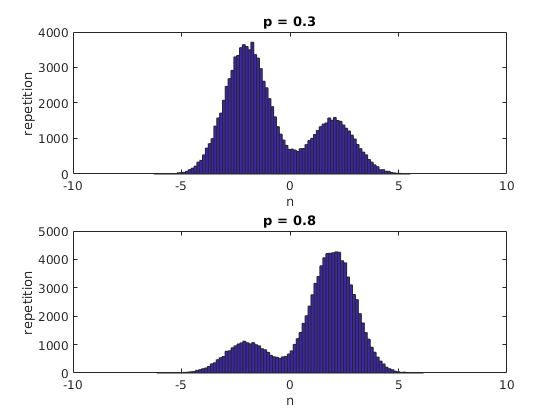

A = 2; sigma = 1; size = 100000; p=0.5;
figure;
subplot(2,1,1);
rec = awgn_ch(A , sigma , size , 0.3);
hist(rec , nbins);
title('p = 0.3');xlabel('n');ylabel('repetition');xlim([-10,+10]);

subplot(2,1,2);
rec = awgn_ch(A , sigma , size , 0.8);
hist(rec , nbins);
title('p = 0.8');xlabel('n');ylabel('repetition');xlim([-10,+10]);

Probability of Error of AWGN:

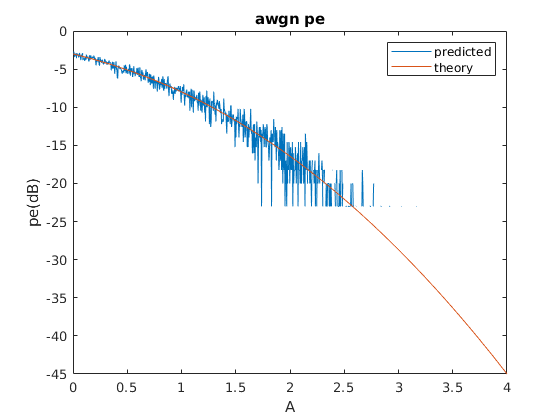

alim = 4; size= 1000; rep=100;
[pred , th , a] = plt_data(alim , size , rep);

figure;
plot(a , 10*log10(pred) , 'DisplayName','predicted');
hold on;
plot(a,10*log10(th),'DisplayName','theory');
hold off;
title('awgn pe(rep = 100)');xlabel('A');ylabel('pe(dB)');
legend;

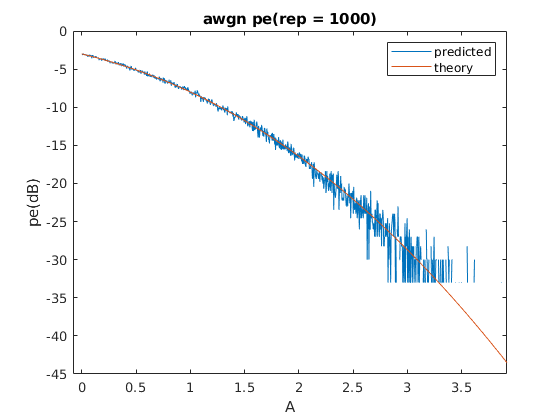

alim = 4; size= 1000; rep=1000;
[pred , th , a] = plt_data(alim , size , rep);

figure;
plot(a , 10*log10(pred) , 'DisplayName','predicted');
hold on;
plot(a,10*log10(th),'DisplayName','theory');
hold off;
title('awgn pe(rep = 1000)');xlabel('A');ylabel('pe(dB)');
legend;

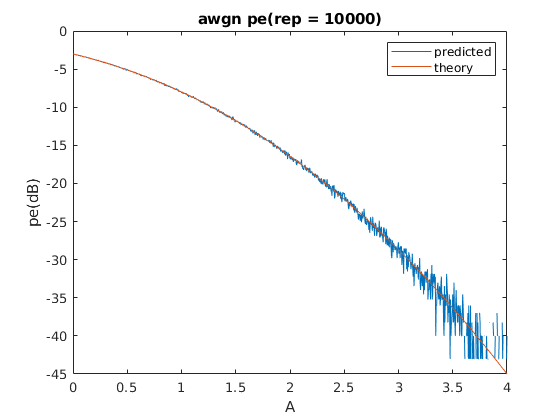

alim = 4; size= 1000; rep=10000;
[pred , th , a] = plt_data(alim , size , rep);

figure;
plot(a , 10*log10(pred) , 'DisplayName','predicted');
hold on;
plot(a,10*log10(th),'DisplayName','theory');
hold off;
title('awgn pe(rep = 10000)');xlabel('A');ylabel('pe(dB)');
legend;